## Lectura de capas

layerfolder = "Capas/Capas_SouthAmerica_2.5M/"; %route to folder with ambiental data
Dimensions = ReadLayers(layerfolder);

----Reading layers----
Elapsed time is 49.595483 seconds.


## Generación de especie virtual

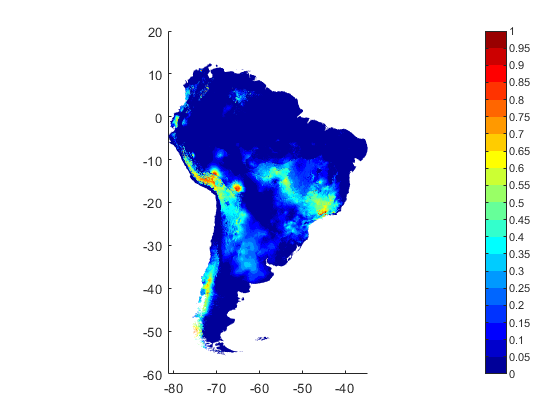

close all
InfoInitialPoint = InitialPoint(Dimensions);
MapInfo = VirtualSpecies(Dimensions, InfoInitialPoint, 0.5, true);

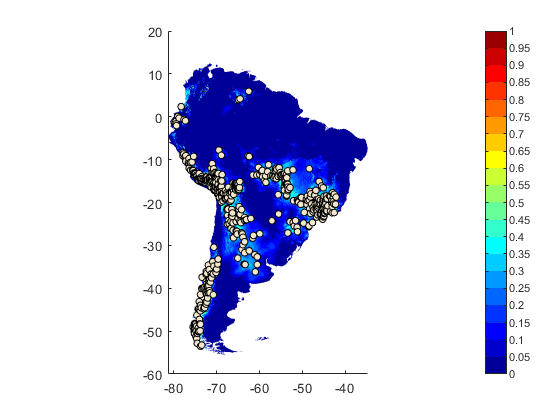

T = samplingVS(Dimensions, MapInfo, 500, -3, true, 'GenSP', true, true);

## Modelamiento con clusters

----Finding clusters----
2 clusters identified


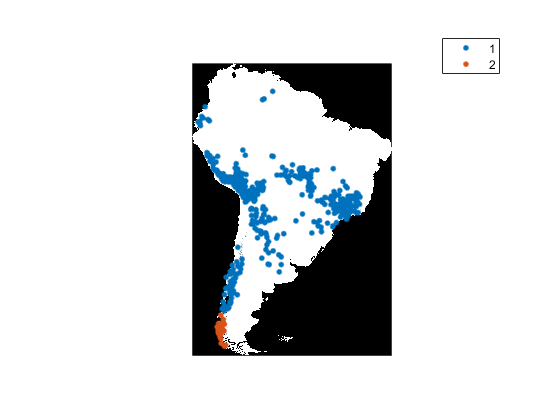

----Finding correlation----
Elapsed time is 3.053567 seconds.
----Creating predictors----
----Finding correlation----
Elapsed time is 3.834020 seconds.
----Creating predictors----
Elapsed time is 3.880252 seconds.
¡All done!


close all
data = bnm_prep(T, Dimensions, false, 0.7, true);

----Modeling----
-Model 1
-Model 2


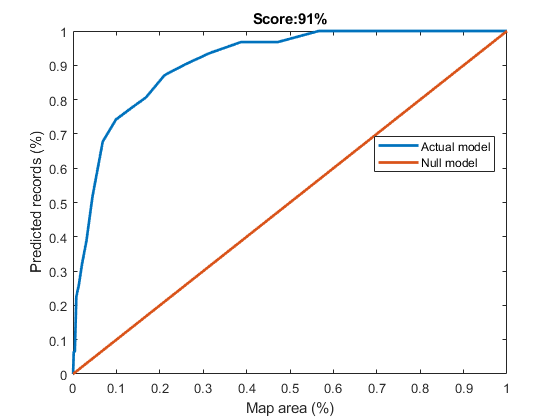

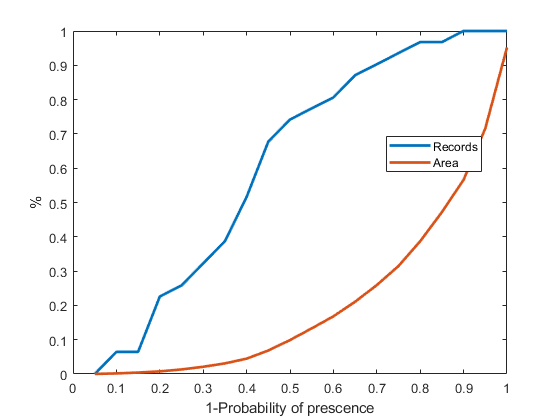

Elapsed time is 5.596888 seconds.


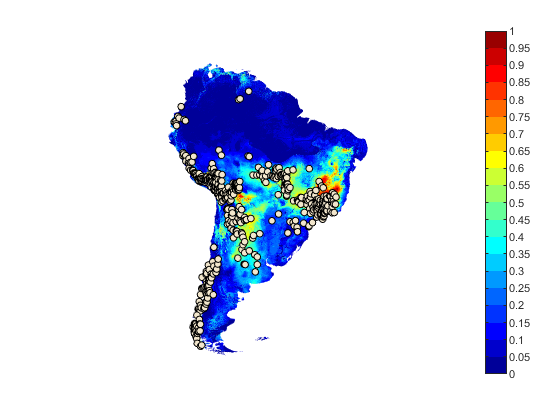

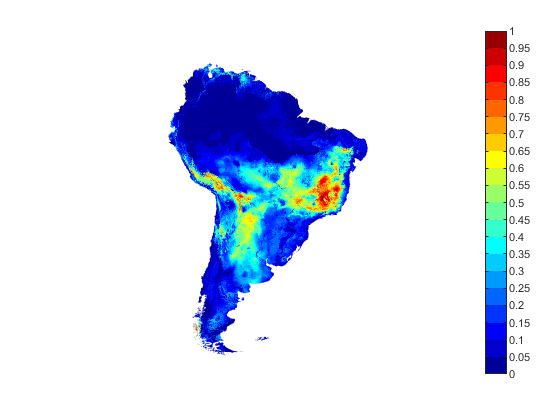

data = bnm_modeling(data, '', true);

## Modelamiento sin clusters

close all
data2 = bnm_prep(T, Dimensions, false, 0.7, false);

----Finding correlation----
Elapsed time is 2.951677 seconds.
----Creating predictors----
Elapsed time is 2.989449 seconds.
¡All done!


----Modeling----
-Model 1


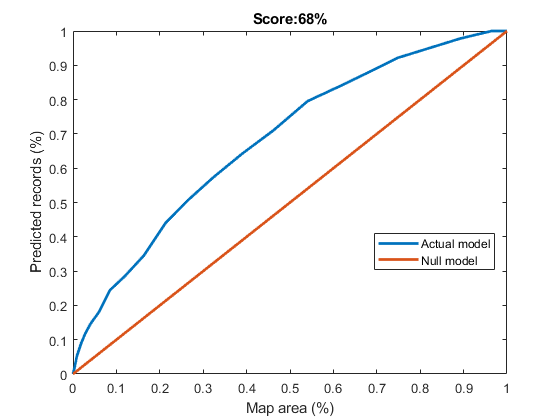

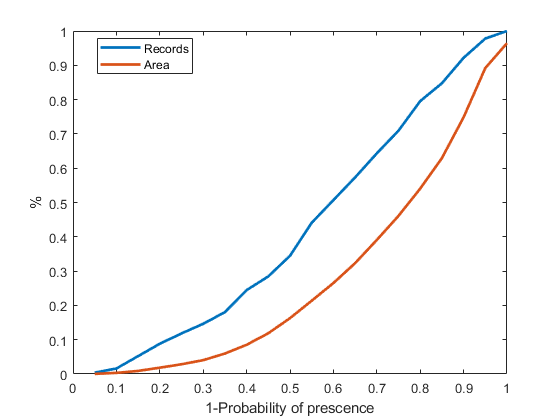

Elapsed time is 2.762933 seconds.


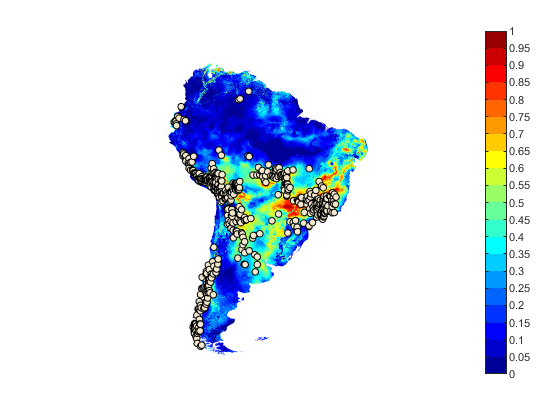

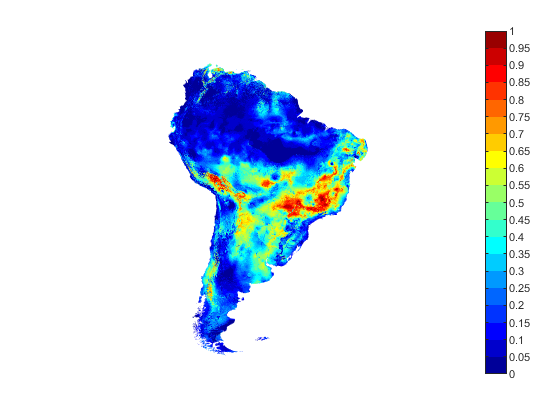

data2 = bnm_modeling(data2, '', true);

## Rendimiento del modelo con clusters

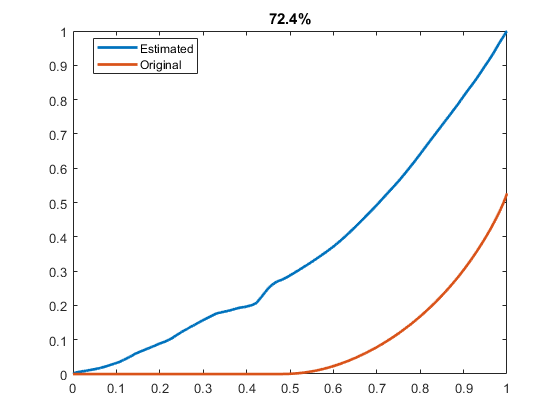

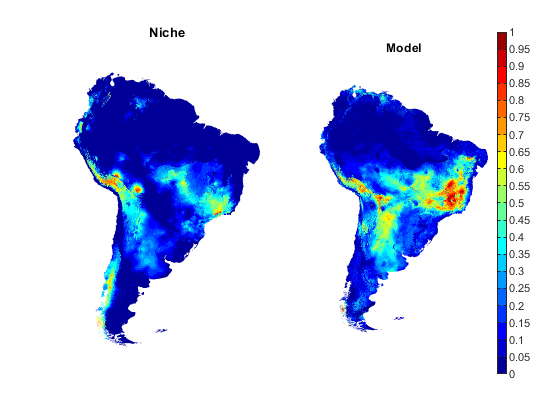

VectorMet =     0.7240    0.8540


VectorMet = MapMetric(MapInfo.Map, data.Map, true, data.R)

## Rendimiento del modelo sin clusters

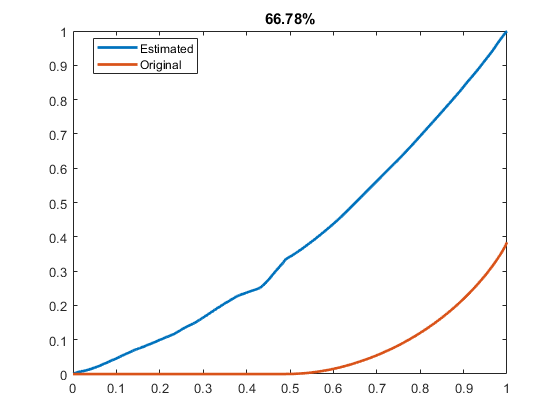

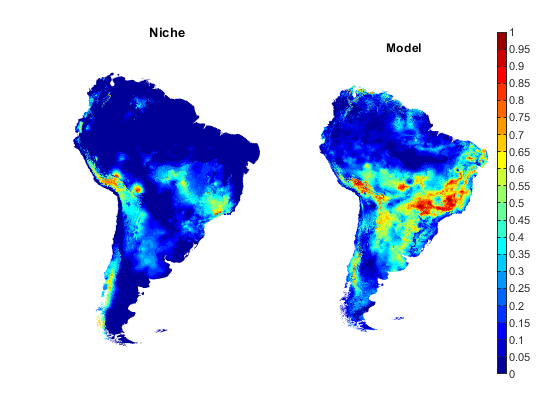

VectorMet =     0.6678    0.7942


VectorMet = MapMetric(MapInfo.Map, data2.Map, true, data2.R)